# Chapter One Introduction 

## What is Computational Statistics

Obviously, computational statistics relates to the tradiontional discipline of statistics. So, before we define computational statistic proper, we need to get a handle on what we mean by the filed of statistics. At a most basic level, statistics is concerned with the transformation of raw data into knowledge. 

Statistics is concerned with the science of uncertainty and ca help the scientist deal with these questions. Many classical methods (regression, hypothesis testing, parameter estimation, confidence intervals, etc.) of statistics developed over the least century are familiar to scientists and are widely used in many disciplines. 

Now, what do we mean by computational staistics? Here we agian followi the definition given in Wegman [1988]. Wegman defines computational statisticsas as a collection of techiniques that have a strong " focus on the exploitation of computing in the creation of new statistical methodology." 

Many of these methodologies became feasible after the development of inexpensive computing hard ware since the 1980's. This computing revolution has enabled scientists and engineers to store and process massive amount of data. However these data are typically collected without a clear idea of what they will be used for in a study. For instance, in the practice of data analysis today, we often collect the data and then we design a study to gain some useful information from them. In contrast, the traditional approach has been to first design the study based on research questions and then collect the required data. $\dots$ 

Here is the link of the Computational Statistics Toolbox provided by the book *Computational Statistics Handbook with MATLAB* http://www.pi-sigma.info/CS2E.htm

# Chapter Two Probability Concepts

PS. I don t want to introduce the probability concepts anymore since I have wrote these in my other repos: Use Python Series, you can check it out if you want. 

Here, I will introduce the MATLAB code: 

## Binomial Distribution 

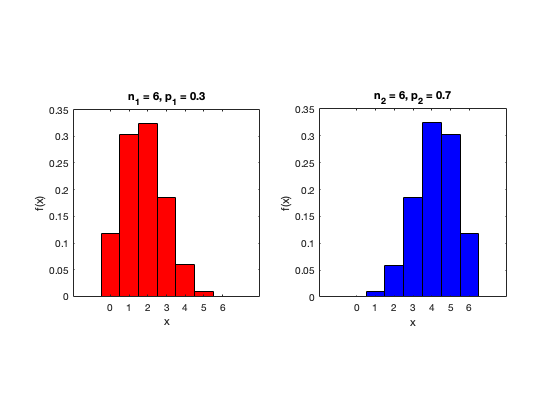

% X is a binomial random variablw with parameters (25, 0.2)
% In MATLAB we use `binocdf` or `binopdf`

prob_bino = binocdf(3,  25, 0.2); % the probability of X less than 3 
prob_bino2 = sum(binopdf(0:3, 25, 0.2)); % the sum of the PDF from 0 to 3 

% this two commands have the same return 

% Get the values for the domain, x. 
x = 0:6; 
% Get the values of the probability density function 
% First for n = 6, p = 0.3
n_1 = 6; p_1 = 0.3;
pdf1 = binopdf(x, n_1, p_1);
%Second for n = 6, p = 0.7
n_2 = 6; p_2 = 0.7;
pdf2 = binopdf(x, n_2, p_2);
% Do the plots 
subplot(1, 2, 1), bar(x, pdf1, 1, 'red')
title("n_1 = 6, p_1 = 0.3")
xlabel("x"), ylabel("f(x)")
axis square
subplot(1,2,2), bar(x, pdf2, 1,'blue')
title("n_2 = 6, p_2 = 0.7")
xlabel("x"), ylabel("f(x)")
axis square;

I have showed you how to calculate the PDF and CDF of Binomial Distribution, also how to draw the plot. 

## Poisson Distribution 

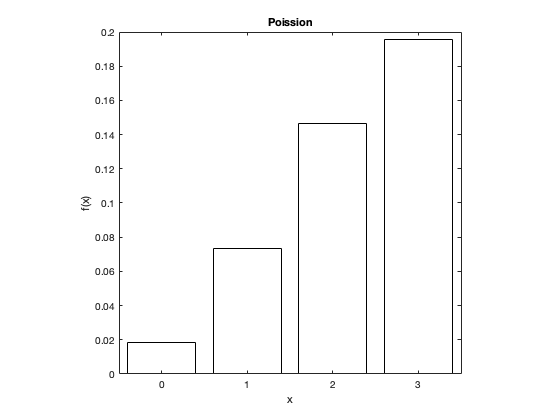

% this is another way to calculate the cdf and pdf 
% X = 3, lambda = 4
X = 0:3; lambda = 4;
prob_P = cdf("Poisson", 3, 4);
Pro_P2 = sum(pdf("Poisson",0:3, 4));
pdf_P = poisspdf(X, 4);
subplot(1,1,1), bar(X, pdf_P, 'white')
title("Poission")
xlabel("x"), ylabel("f(x)")
axis square

## Uniform Distribution 

We illustrate the uniform probability density function over the interval $(0, 10)$, along with the corresponding cumulative distribution function. The MATLAB Statistics and Machine Learning Toolbox function `unifpdf` and `unifcdf` are used to get the desired functions over the interval. 

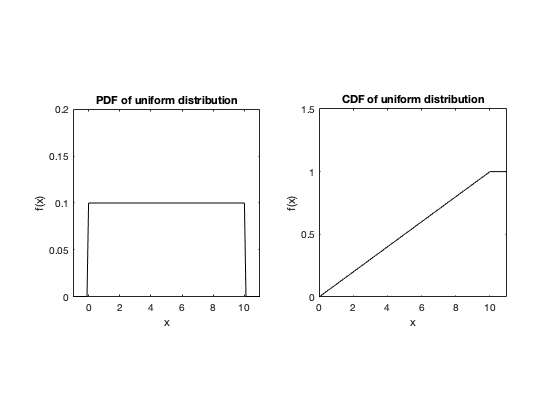

% get the domin over which we will
% evaluate the functions 
x = -1:.1:11;
% get the probability density function values at x
pdf = unifpdf(x, 0, 10);
% get the cumulate density function 
cdf = unifcdf(x, 0, 10);

%plot pdf & cdf
subplot(1,2,1);
plot(x,pdf, 'black');
title("PDF of uniform distribution");
xlabel("x"), ylabel("f(x)")
axis([-1 11 0 0.2]);
axis square

subplot(1,2,2);
plot(x,cdf, 'black');
title("CDF of uniform distribution");
xlabel("x"), ylabel("f(x)");
axis([0 11 0 1.5]);
axis square

## Normal Distribution

Similar to the uniform distribution, the functions `normpdf` and `normcdf` are avialbe in the MATLAB Statistics Toolbox for calculating the probability density function and culmulative distribution function for the normal. There is also another special function called `normspec` that determins the probability that a random varaible `X` assumes a vlue between two limits, where `X` is normally distriubted with mean $\mu$ and standard deviation $\sigma$. Ths function also plots the normal density, where the area between the specified limits is shaded.

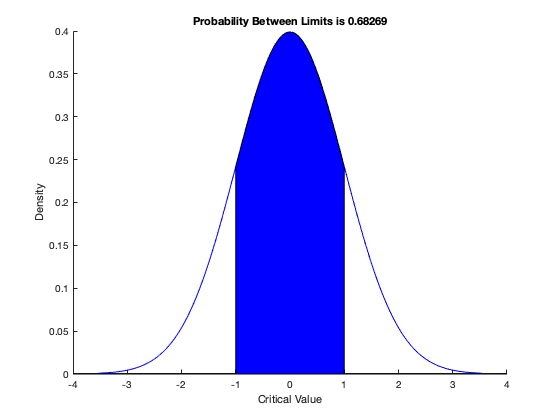

% set up the parameter for the normal distribution 
mu = 0;
sigma = 1;
% Set up the upper and lower limits, these are in the two element vector 'specs'
specs = [-1, 1];
prob = normspec(specs, mu, sigma, "inside");

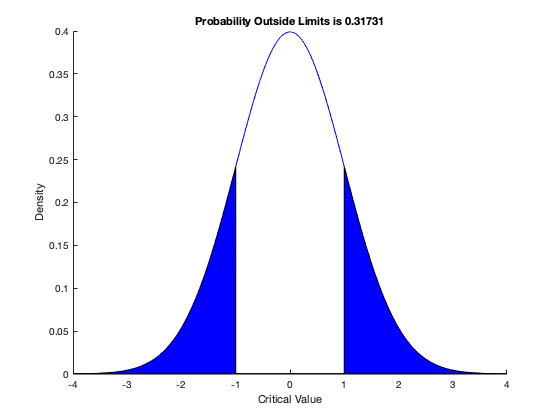

prob2 = normspec(specs, mu, sigma, "outside");

## Exponential Distribution

The time between arrival of vehicles at an intersection follows an exponential distirbution with a mean of $12$ seconds. What is the probability that the time between arrivals is $10$ seconds or less? We are given the average interatival time, so $\lambda =\frac{1}{12}$   . The required probability is 


$$P(X \leq 10) = 1 - e^{- \frac{1}{12} \times 10} \approx 0.57$$
 

You can calculate this using the MATLAB Statistics Toolbox function `expocdf(x, 1/lambda)` . NOte that this MATLAB function is based on a different definition of the exponentional probability density function, which is given by :


$$f(x;\mu) = \frac{1}{\mu} e^{-\frac{x}{\mu}}; \ \ x \leq 0 ; \mu > 0.$$
 

In the Computational Statistics Toolbox, we include a function called `csexpoc(x, \lambda)` 

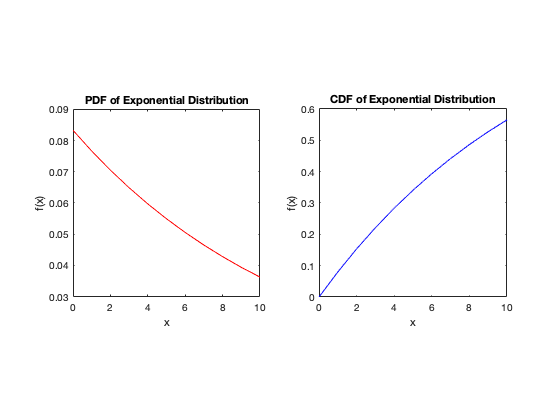

x = 0:10;
pdf = exppdf(x, 12);
cdf = expcdf(x, 12);

subplot(1,2,1);
plot(x,pdf,'red')
xlabel('x'); ylabel('f(x)');
title('PDF of Exponential Distribution');
axis square

subplot(1,2,2)
plot(x,cdf, 'blue')
xlabel('x'); ylabel('f(x)');
title('CDF of Exponential Distribution');
axis square

## Gamma

We plot the gamma probability density function for $\lambda = t = 1$ ( this should look like the exponential ), $\lambda = t = 3$. You can use the MATLAB Statistics Tool box function `gampdf(x, t, 1/lambda)` or the function `csgammp(x, t, \lambda)`

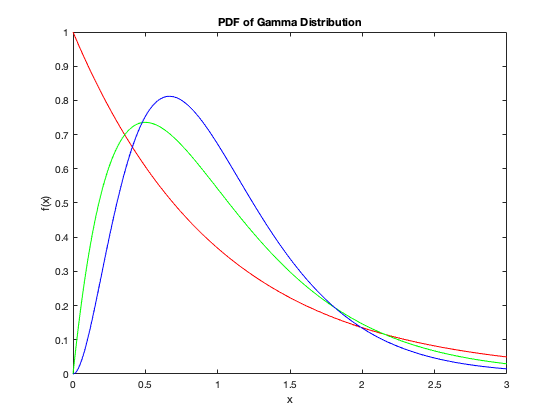

% get the domin over which to evaluate the functions
x = 0:.01:3;
% get the functions values for  different values of lambda 
y1 = gampdf(x, 1, 1/1);
y2 = gampdf(x, 2, 1/2);
y3 = gampdf(x, 3, 1/3);

%plot the functions 
subplot(1,1,1);
plot(x, y1,'r', x, y2, 'g', x, y3, 'b');
title('PDF of Gamma Distribution');
xlabel('x'); ylabel('f(x)')

## Chi-Square

If we difine a gamma distribution with $\lambda = 0.5$ and $t = \frac{v}{2}$ , with $v$ a positive interger, we can call this distribution **Chi-square Distribution. **

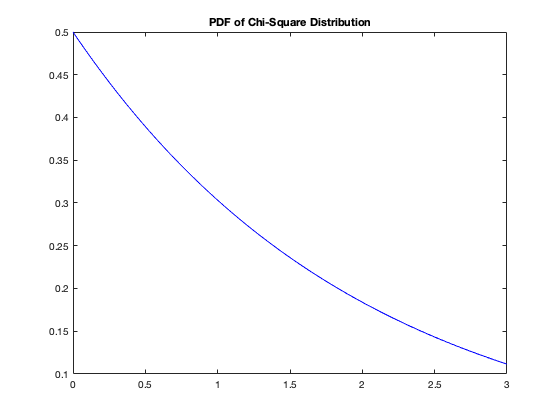

chi2_pdf = chi2pdf(x,2);
subplot(1,1,1);
plot(x,chi2_pdf,'b')
title('PDF of Chi-Square Distribution')

## Weibull Distribution

The exponential distribution has a constant hazard function, which is not generally the case for the Weibull distribution. The plot shows the hazard function for exponential (dashed line) and Weibull (solid line) distributions having the same mean life. The Weibull hazard rate here increases with age (a reasonable assumption).

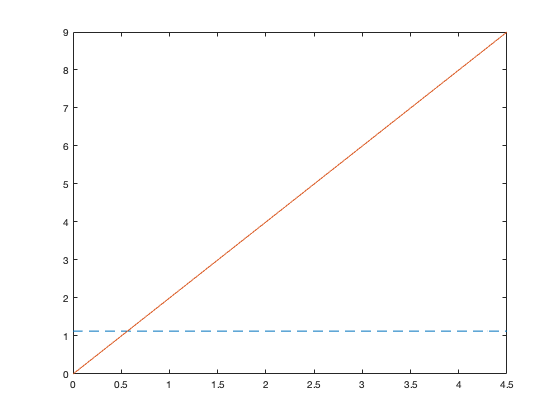

t = 0:0.1:4.5;
h1 = exppdf(t,0.8862)./(1-expcdf(t,0.8862));
h2 = wblpdf(t,1,2)./(1-wblcdf(t,1,2));
plot(t,h1,'--',t,h2,'-')

## Beta Distribution

We use the following MATLAB code to plot the beta density over the interval $(0, 1)$. We let $\alpha = \beta = 0.5#$ and $\alpha = \beta = 3$ 

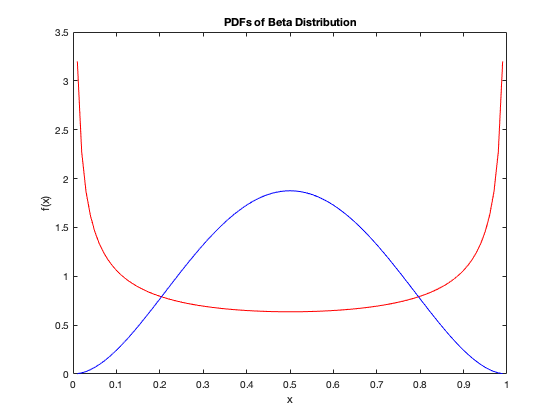

% get the domain over which to evaluate the density function 
x = 0.01:.01:.99;
%get the values for the density function 
y1 = betapdf(x, 0.5, 0.5);
y2 = betapdf(x, 3, 3);
%plot the results 
plot(x, y1, 'r', x, y2, 'b');
title('PDFs of Beta Distribution')
xlabel('x'); ylabel('f(x)')

## Multivariate Normal Distribution

We first provide the following MATLAB function to calculate the multivaraite normal probaility density function and illustrate its use in the bivariate case. The function is called `mvnpdf` to calculate the PDF and `mvncdf` to calculate the CDF. 

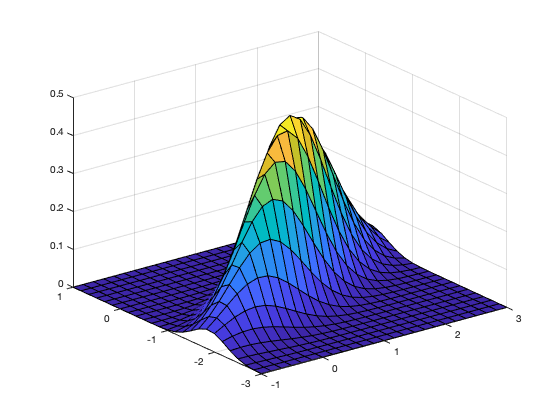

mu = [1 -1];
SIGMA = [.9 .4; .4 .3];
figure;
[X1,X2] = meshgrid(linspace(-1,3,25)',linspace(-3,1,25)');
X = [X1(:) X2(:)];
pdf = mvnpdf(X,mu,SIGMA);
surf(X1,X2,reshape(pdf,25,25));

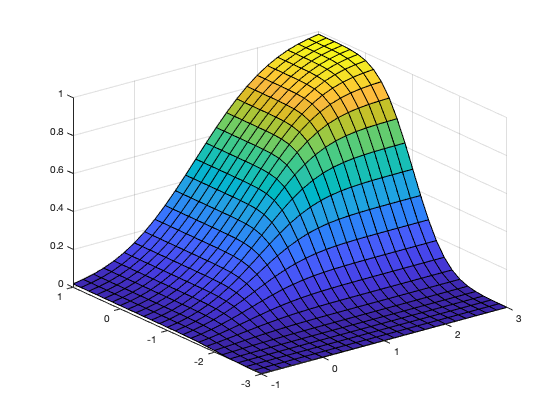

cdf = mvncdf(X,mu,SIGMA);
surf(X1,X2,reshape(cdf,25,25));

# Sampling Concept

## Introduction

In this chapter, we cover the concepts associated with random sampling and the sampling distirbution of statistics. These notionsa are fundamental to  computational statistics and are needed to understand the topcis covered in the rest of this Note. 

## Sample Mean and Sample Variance

A familiar statistic is the **sample mean** given by $\displaystyle \bar{X} = \frac{1}{n} \sum^n_{i=1} X_i$ .  To calculate this in MATLAB, one can use the function called 

`mean` If the argument to this function is a matrix, then it provides a vector of  means, each one corresponding to the mean of a column. 

x = [1 2 3 4 5 6 7 8 9 10];
mean(x)

ans = 5.5000

y = [1 2 3; 2 3 4; 3 4 5];
mean(y) == mean(y,1) % default mode: mean by column 

ans = 1×3 logical array
   1   1   1


One can find the mean along any dimension  of multi-dimensional arrays using the syntax: `mean(x,dim)`

mean(y,2) % mean by column 

ans =      2
     3
     4


`Another statistic that we will see agian is the ``sample varaince``, or ``standard deviation``, calculated from `$\displaystyle S^2 = \frac{1}{n - 1} \sum_{i=1}^n (X_i - \bar{X})^2 = \frac{1}{n \ n -1}\Big[n \sum_{i=1}^n X_i^2 - \Big(\sum_{i=1}^n X_i\Big)^2\Big]$

`So, `$Var = std^2$ , in MATLAB, we can use `std(A)` and `var` to calculate standard deviation and variance respectively. Here is the example: 

var(x); % variance of x
std(x); % std of x
var(x) == std(x) ^ 2 % to check whether they are equals

ans = logical
   0


`Why the answer is `$0$ (FALSE)? That is because the computer can not get the exact value of the floating number. We can consider they are the same mathemetically but not in computer. Usually, if we want to compare two equation, we will give a tolerance $\epsilon$, if the difference's absolute value is samller than the $\epsilon$, we will consider the two equations' solution is the same. This is the **limit theroem.**

## **Sample Moments**

The sample moments can be used to estimate the population moments, The **r-th sample moment** about zero is given by 


$$\displaystyle M'_r = \frac{1}{n}\sum_{i=1}^n X_i^r$$


`Note that the sample mean is obtained when `$r = 1$. The $r-$th sample moments about the sample mean are statstics that estimate the **population central moments** and can be found using the following: 


$$M_r = \frac{1}{n}\sum_{i=1}^n X_i - \bar{X})^r$$


We use this equation to obtain estimates for the coefficient of skewness $\gamma_1$ and the coefficient of kurtosis $\gamma_2$ . Recall that these are given by: 


$$
\gamma_1 = \frac{\mu_3}{\mu_2^{\frac{3}{2}} \\ 
\gamma_2 = \frac{\mu_4}{\mu_2^2}
$$


Substituting the sample moments for the population moments in those equations, we have: 


$$\hat{\gamma_1} = \frac{\frac{1}{n}\sum_{i=1}^n X_i - \bar{X})^3}{\Big(\frac{1}{n}\sum_{i=1}^n X_i - \bar{X})\Big)^{\frac{3}{2}}

$$



$$\hat{\gamma_2} = \frac{\frac{1}{n}\sum_{i=1}^n X_i - \bar{X})^4}{\Big(\frac{1}{n}\sum_{i=1}^n X_i - \bar{X})\Big)^{2}$$


We are using the 'hat' notation to denote an estimate. Thus $\hat{\gamma_1}$, is an estimate for $\gamma_1$. The following example shows how to use MATLAB to obtain the sample coefficient of skewness and sample coefficient of kurtosis. 

In this exampl, we will generate a random sample that is uniformly distrbuted over the interval $(0, 1)$. We would expect this sample to have a coefficient of skewness close to zero because it is a symmetric distribution. We would  expect the kurtosis to be different from $3$, because the random sample is not generated from a normal distribution. 

% Generate a random sample from the uniform 
% distribution
n = 200;
x = rand(1,200); % uniform distribution random number 
% Find the mean of the sample 
mu = mean(x);
% Find the numerator and denominator for gamma_1 
num = (1/n) * sum((x - mu).^ 3);
den = (1/n) * sum((x - mu).^2);
gam1 = num / den^(3/2);

This gives a skewness of `gam1 = -0.0893`, which is not too far from zero. Now we find the kurtosis using the following MATLAB commands:

% Find the kurtosis
num = (1/n) * sum((x - mu) .^ 4);
den = (1/n) * sum((x - mu) .^ 2);
gam2 = num / den ^ 2; 

The kurtosis of `gam2 =  1.6789`, which is not close to $3#$, ass expected . 

## Covariance

In the definitions fiven given below, we assume that all expectations exist. The **convariance** of two random varaibles $X$ and $Y$, with joint probability density function $f(x, y)$, is defined as 


$$Cov(X, Y) = \sigma_{X, Y} = E[(X - \mu_x) (Y - \mu_Y)]$$


The *correlation coefficient* of $X$ and $Y$ is given by: 


$$Corr(X, Y) = \rho = \frac{Corr(X, Y)}{\sigma_X \sigma_Y} = \frac{\sigma_{X, Y}}{\sigma_X \sigma_Y}$$


where $\sigma_X > 0$ and $\sigma_Y > 0$ 

The correlation is a measure of the linear relationship between two random varaibles. If the joint distribution of two variables has a correlation coeficient, then $-1 \leq \rho_{X, Y} \leq 1$, then $X$ and $Y$ are perfectly positively correlated. This means that the possible valeus for $X$ and $Y$ lie on a line with positive slope; on the other hand, when $\rho_{X, Y} = -1$, then the situation is the opposite. It $X$ and $Y$ are independent, then $\rho_{X, Y} = 0$. Note that the converse of this statement not necessarily hold. 

There are statistics that can be used to estimate these quantities. Let's say we have a random saple of size $n$ denoted as $(X_1, Y_1), \dots, (X_n, Y_n)$. The sample covariance is typically calculated using the following statistic: 


$$\hat{\sigma_{X, Y}} = \frac{1}{n - 1} \sum_{i = 1}^n (X_i - \bar{X})(Y_i - \bar{Y})$$


In MATLAB, we can use `cov `to calculate. For the correlation coefficient, we can do the same thing. 


$$\hat{\rho} = \frac{\frac{1}{n - 1} \sum_{i = 1}^n (X_i - \bar{X})(Y_i - \bar{Y})}{\Big( \sum_{i = 1}^n (X_i - \bar{X})\Big)^{\frac{1}{2}} \Big(\sum_{i = 1}^n (Y_i - \bar{Y})\Big)^{\frac{1}{2}}$$


In this example, we show how to use the MATLAB `cov` function to find the covariance between two varaibles and the `corrcef` function to find the correlation coefficient. both of these function are aviralbe in the standard anlalyzed Hald[1952], to illustrate the basic syntax of these functions. The relationship between the two varaibles is nonlinear, so Hald looked at the log of the tensile strength as a function of the reciprocal of the drying time. When the `cement` data are loaded, we get a vector `x` representing the drying times and a vector `y` that contains the tensile strength. 

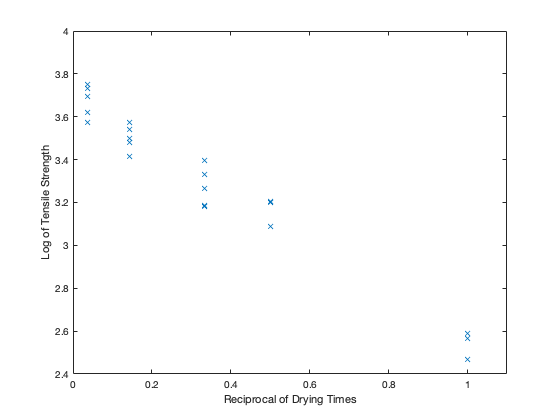

clear all;
% First load the data. 
load ('/Volumes/Storage/computation statistics/CSToolbox V3/cement.txt');
% get the transformations 
xr = 1./cement(:,1);
logy = log(cement(:,2));
%get a sctterplot of the data to see if the relationship is lienar 
plot(xr, logy, 'x')
axis([0 1.1 2.4 4])
xlabel('Reciprocal of Drying Times')
ylabel('Log of Tensile Strength')

We now show how to get the covariance matrix and the correlation coefficient for these two varaibles:

% get the covariance and the coreelation coefficient
cmat = cov(xr, logy)

cmat =     0.1020   -0.1169
   -0.1169    0.1393


cormat = corrcoef(xr, logy)

cormat =     1.0000   -0.9803
   -0.9803    1.0000


## Bias

The bias in a estimator gives a measure of how much error we have, on average, in our estimate when we use $T$ to estimate our parameter $\theta$. The **bias** is defined as 


$$bias(T) = E[T] - \theta$$


If the estimator is unbiased, then the expected value of our estimator equals the true parameter values, $E[T] = \theta$

To determine the expected valeus in the equation above, we must know the distribution of the statistic $T$. In these situation, the bias can be determined andlytically. When the distribution of statistic is not known, then we can use methods suck as the jackknife the the bootstrap to estimate the bias of $T$. 

## Mean Squared Error

Let $\theta$ denote the parameter we are estimating and $T$ denote our estimate, then the **mean squared error(MSE)** of the estimator is defined as 


$$MSE(T) = E[(T - \theta)^2].$$


Thus, the MSE is the expected values of the squared error. We can write this in more useful quantities such as the bias and variance of $T$. If we expand the expected value on the right had side of the equation, then we have 


$$MSE(T) = E[T^2 - 2T\theta + \theta^2] = E[T^2] - 2\theta E[T] + \theta^2 $$


By adding and subtrating $(E[T])^2$ to the right hand side of Equation . we have the the following ;


$$MSE(T) = E[T^2] - (E[T^2] - (E[T])^2 + (E[T])^2 - 2\theta E[T] + \theta^2 \Rightarrow Var(T) + [bias(T)]^2 $$


## Relative Efficinecy

Another measure we can use to compare estimator is called efficiency, which is defined using the MSE. For example, suppose we have two estimators $T_1 = t_1(X_1, \dots, X_n)$ and $T_2 = t_2(X_1, \dots, X_n)$ for the same parameter. if the MSE of one estimator is less than the other $(e.g.m MSE(T_1) < MSE(T_2))$, then $T_1$ is said to be more efficient than $T_2$. 

The **relative efficiency** of $T_1$ to $T_2$ is given by 


$$eff(T_1, T_2) = \frac{MSE(T_2)}{MSE(T_1)}$$


If the ratio is greater tahn one, then $T_1$ is a more efficient estimator of the parameter. 

## Standard Error

We can get a measure of the precision of our estimator by calculating the standard error. The **standard error** of an estimator (or a statistic) is defined as the standard deviation of its sampling distribution: 

$SE(T) = \sqrt{V(T)} = \sigma_T$.

To illustrate this concept, let's use the sample mean as an example. We know that the varaince of the estimator is 


$$V(\bar{X}) = \frac{1}{n}\sigma^2$$


for large $n$. So, the standard error is given by 


$$SE(\bar{X}) = \sigma_{\bar{X}} = \frac{\sigma}{\sqrt{n}}$$


If the standard deviation $\sigma$ for the underlying population is unknonw, then we can substitue an estimate for the parameter. in this case, we call it the estimated standard error:


$$\hat{SE}(\bar{X}) = \hat{\sigma}_{\bar{X}} = \frac{\sigma}{\sqrt{n}}$$


## Maximum Likelihood Estimation

A **maximum likelihood estimator is that value of the paramter (or parameters) taht maximizeds the likelihood funcion of the sample. The **likelihood funcion** of a random sample of size $n$ from density (mass) function $f(x;\theta)$ is the joint probability density (mass) function, denoted by: 


$$L(\theta;x_1, \dots, x_n) = f(x_1, \dots, x_n; \theta)$$


This equation provides the likelihood that the random varaibles take on a particular values$x_1, \dots, x_n$. Note that the likelihood function $L$ is a function of the unknown parameters $\theta$, and that we allow $\theta$ to represent a vecotr of parameters. 

If we have a random sample (independent, identically dsitributed random varaibles), then we can write the likelihood function as 


$$L(\theta) = L(\theta; x_1, \dots, x_n) = f(x_1; \theta) = f（x_1; \theta) \times \dots \times f(x_n; \theta)$$


which is the product of the individual denstiy function evaluated at each $x_i$ or sample point. 

In most cases, to find the value $\theta$ taht maximizes the likelihood function, we take the derivative of $L$, set it equal to $0$ and solve for $\theta$. Thus, we solve the following likelihood equation


$$\frac{d}{d\theta}L(\theta) = 0$$


It can be shown that the likelihood function, $L(\theta)$, and logarithm of the likelihood function, $LogL(\theta)$,a have their maxima at the same value of $\theta$. It is sometimes easier to find the 